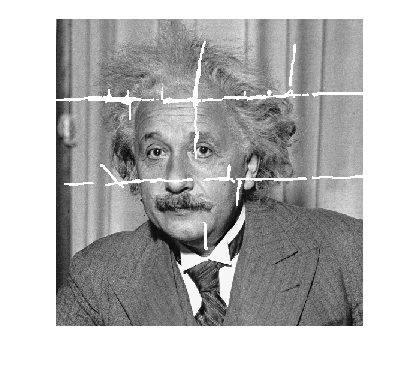

I=imread("EINSTEIN.tif");
g=im2gray(I);
[r c]=size(g);
t=[];

for i=1:1:r

    for j=1:1:c

        if g(i,j)==255
                 
          t(i,j)=0;

        else

           t(i,j)=255;

        end    

    end

end



bin_img=uint8(t);
imshow(g)

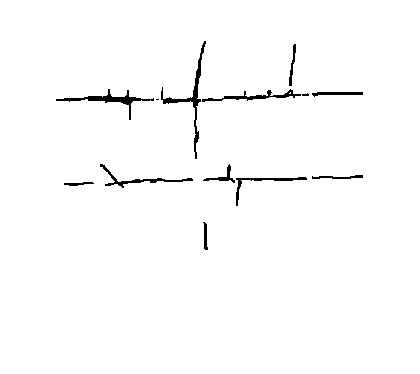

imshow(bin_img)

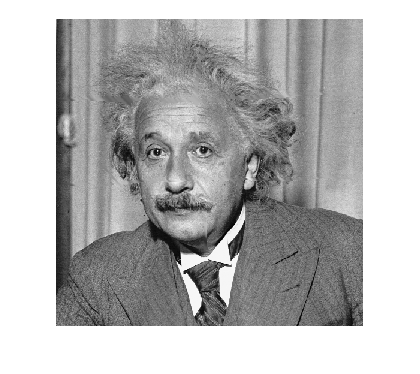




for i=1:1:r

    for j=1:1:c

        if g(i,j)==255
                 
         if i==1
             g(i,j)=g(i,j-1);    
         end    

         if j==1
            g(i,j)=g(i-1,j);
         end

         if i~=1 && j~=1
            g(i,j)=g(i,j-1)/3 + g(i-1,j-1)/3 + g(i-1,j)/3  ;
         end   

    end

    end
end
    imshow(g)


score1= brisque(g) 

score1 = 29.6109

score2= niqe(g)

score2 = 5.2155

score3= piqe(g)

score3 = 40.8674